Reading the clusters and spike times from Phy into data matrix (404 x 3595320)

spike_clusters = readNPY('spike_clusters.npy');
spike_times = readNPY('spike_times.npy');

bin_size = 1; % in milliseconds
total_time = max(spike_times); % the entire recording duration
time_bins = 0:bin_size:total_time; % creates an array of bin edges

unique_clusters = unique(spike_clusters); % array with unique cluster IDs
num_clusters = length(unique_clusters); % number of unique cluster IDs
spike_matrix = zeros(num_clusters,length(time_bins)-1); % clusters by time bins data matrix

for i = 1:num_clusters  % iterate through clusters
    curr_cluster = unique_clusters(i); 
    curr_times = spike_times(spike_clusters == curr_cluster); % extract array of spike times for current cluster via logical indexing

    spike_counts = histcounts(curr_times, time_bins); % counts the number of spikes that fall in each time bin (1 or 0)
    spike_matrix(i,:) = spike_counts; % adds the spike counts at each column (time bin), row by row (clusters)
end

Overview and visualisation

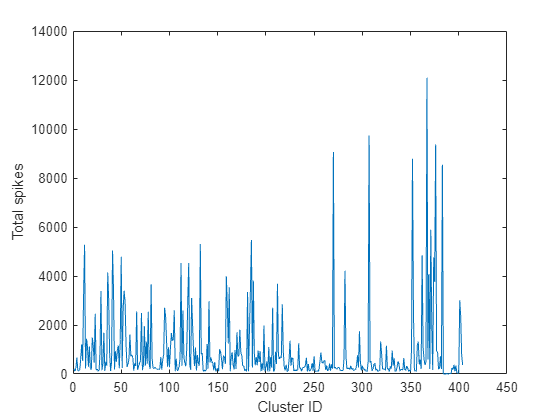

spikes_per_cluster = sum(spike_matrix,2);
figure;
plot(spikes_per_cluster);
xlabel('Cluster ID');
ylabel('Total spikes');

Convolving the matrix with Gaussian kernel: 

bin_size = 1;  % 1 ms
kernel_width = 50;  % total width of the kernel, 50ms in this case
sigma = 10;  % standard deviation, 10ms in this case

% Define Gaussian function
gauss_kernel = fspecial('gaussian', [1, kernel_width], sigma/bin_size);

% Normalize to ensure the area under the kernel is 1
gauss_kernel = gauss_kernel / sum(gauss_kernel);

rate_matrix = conv2(spike_matrix,gauss_kernel,'same'); %convolving our 2D spike matrix with 1D gaussian kernel

